# Fracture length distribution fitting with/without censoring

## Import data from CSV file

% File name
filename = "F:\Dottorato\Truncation_censoring_test\length_dist.csv";

% Import code auto-generated by MATLAB - do not edit if it works

% Initialize options
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Unodes", "length"];
opts.SelectedVariableNames = ["Unodes", "length"];
opts.VariableTypes = ["string", "string", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2"], "EmptyFieldRule", "auto");

% Import the data
length_data = readtable(filename, opts);

% Convert table to matrix
length_data = table2array(length_data)

length_data =     1.0000    1.6620
    1.0000    2.8740
         0    1.8720
         0    3.3570
         0    0.8980
    1.0000    1.0430
         0    0.8330
         0    0.5850
         0    0.5370
    1.0000    0.7050



% Clear import options
clear opts

## Statistical analysis

% create empirical cumulative distribution - ECDF - from data
[ecdf_NC_cfr, ecdf_NC_val] = ecdf(length_data(:,2));
[ecdf_C_cfr,ecdf_C_val] = ecdf(length_data(:,2),'censoring',length_data(:,1));

% fit distribution
LognormDist_NC = fitdist(length_data(:,2),'Lognormal');
LognormDist_C = fitdist(length_data(:,2),'Lognormal','censoring',length_data(:,1));
NormDist_C = fitdist(length_data(:,2),'Normal','censoring',length_data(:,1));
ExpDist_C = fitdist(length_data(:,2),'Exponential','censoring',length_data(:,1));
BurrDist_C = fitdist(length_data(:,2),'Burr','censoring',length_data(:,1));
GammaDist_C = fitdist(length_data(:,2),'Gamma','censoring',length_data(:,1));
LogisticDist_C = fitdist(length_data(:,2),'Logistic','censoring',length_data(:,1));


% create expected CDF and PDF
expectLognormCdf_NC = cdf(LognormDist_NC,ecdf_NC_val);
expectLognormPdf_NC = pdf(LognormDist_NC,ecdf_NC_val);

expectLognormCdf_C = cdf(LognormDist_C,ecdf_C_val);
expectLognormPdf_C = pdf(LognormDist_C,ecdf_C_val);

expectNormCdf_C = cdf(NormDist_C,ecdf_C_val);
expectNormPdf_V = pdf(NormDist_C,ecdf_C_val);

expectBurrCdf_C = cdf(BurrDist_C,ecdf_C_val);
expectBurrPdf_V = pdf(BurrDist_C,ecdf_C_val);

expectGammaCdf_C = cdf(GammaDist_C,ecdf_C_val);
expectGammaPdf_V = pdf(GammaDist_C,ecdf_C_val);

expectLogisticCdf_C = cdf(LogisticDist_C,ecdf_C_val);
expectLogisticPdf_V = pdf(LogisticDist_C,ecdf_C_val);

% K-S test empirical vs. expected LOGNORMAL NO censoring
[LognormKSHo_NC,LognormKSPval_NC,LognormKSKstat_NC] = kstest2(expectLognormCdf_NC,ecdf_NC_cfr);

Lognorm_NC_txt1 =['K-S test for LogNormal length distribution with μ = ' num2str(LognormDist_NC.mu) ' - σ = ' num2str(LognormDist_NC.sigma)];
Lognorm_NC_txt2 = ['K statistics = ' num2str(LognormKSKstat_NC)];
Lognorm_NC_txt3 = ['p-value = ' num2str(LognormKSPval_NC)];
Lognorm_NC_txt4 = ['Ho = ' num2str(LognormKSHo_NC)];
if LognormKSHo_NC == 0
    Lognorm_NC_txt5 = ['No evidence against Ho of no difference with LogNormal_NC distr. -> Ho retained -> a LogNormal_NC length distribution is detected at 5% significance'];
else
    Lognorm_NC_txt5 = ['Strong evidence against Ho of no difference with LogNormal_NC distr. -> Ho rejected -> no LogNormal_NC length distribution is detected at 5% significance'];
end

% K-S test empirical vs. expected LOGNORMAL with censoring
[LognormKSHo_C,LognormKSPval_C,LognormKSKstat_C] = kstest2(expectLognormCdf_C,ecdf_C_cfr);

Lognorm_C_txt1 =['K-S test for LogNormal length distribution with μ = ' num2str(LognormDist_C.mu) ' - σ = ' num2str(LognormDist_C.sigma)];
Lognorm_C_txt2 = ['K statistics = ' num2str(LognormKSKstat_C)];
Lognorm_C_txt3 = ['p-value = ' num2str(LognormKSPval_C)];
Lognorm_C_txt4 = ['Ho = ' num2str(LognormKSHo_C)];
if LognormKSHo_C == 0
    Lognorm_C_txt5 = ['No evidence against Ho of no difference with LogNormal_C distr. -> Ho retained -> a LogNormal_C length distribution is detected at 5% significance'];
else
    Lognorm_C_txt5 = ['Strong evidence against Ho of no difference with LogNormal_C distr. -> Ho rejected -> no LogNormal_C length distribution is detected at 5% significance'];
end

% K-S test empirical vs. expected NORMAL with censoring
[NormKSHo_C,NormKSPval_C,NormKSKstat_C] = kstest2(expectNormCdf_C,ecdf_C_cfr);

Norm_C_txt1 =['K-S test for Normal length distribution with Mean = ' num2str(NormDist_C.mu) ' - St. dev = ' num2str(NormDist_C.sigma)];
Norm_C_txt2 = ['K statistics = ' num2str(NormKSKstat_C)];
Norm_C_txt3 = ['p-value = ' num2str(NormKSPval_C)];
Norm_C_txt4 = ['Ho = ' num2str(NormKSHo_C)];
if NormKSHo_C == 0
    Norm_C_txt5 = ['No evidence against Ho of no difference with Normal_C distr. -> Ho retained -> a Normal_C length distribution is detected at 5% significance'];
else
    Norm_C_txt5 = ['Strong evidence against Ho of no difference with Normal_C distr. -> Ho rejected -> no Normal_C length distribution is detected at 5% significance'];
end

% K-S test empirical vs. expected BURR with censoring
[BurrKSHo_C,BurrKSPval_C,BurrKSKstat_C] = kstest2(expectBurrCdf_C,ecdf_C_cfr);

Burr_C_txt1 =['K-S test for Burr length distribution with c = ' num2str(BurrDist_C.c) ' - k = ' num2str(BurrDist_C.k) '-  alpha =' num2str(BurrDist_C.alpha)];
Burr_C_txt2 = ['K statistics = ' num2str(BurrKSKstat_C)];
Burr_C_txt3 = ['p-value = ' num2str(BurrKSPval_C)];
Burr_C_txt4 = ['Ho = ' num2str(BurrKSHo_C)];
if BurrKSHo_C == 0
    Burr_C_txt5 = ['No evidence against Ho of no difference with Burr_C distr. -> Ho retained -> a Burr_C length distribution is detected at 5% significance'];
else
    Burr_C_txt5 = ['Strong evidence against Ho of no difference with Burr_C distr. -> Ho rejected -> no Burr_C length distribution is detected at 5% significance'];
end

% K-S test empirical vs. expected GAMMA with censoring
[GammaKSHo_C,GammaKSPval_C,GammaKSKstat_C] = kstest2(expectGammaCdf_C,ecdf_C_cfr);

Gamma_C_txt1 =['K-S test for Gamma_C length distribution with a = ' num2str(GammaDist_C.a) ' - b = ' num2str(GammaDist_C.b)];
Gamma_C_txt2 = ['K statistics = ' num2str(GammaKSKstat_C)];
Gamma_C_txt3 = ['p-value = ' num2str(GammaKSPval_C)];
Gamma_C_txt4 = ['Ho = ' num2str(GammaKSHo_C)];
if GammaKSHo_C == 0
    Gamma_C_txt5 = ['No evidence against Ho of no difference with Gamma_C distr. -> Ho retained -> a Gamma_C length distribution is detected at 5% significance'];
else
    Gamma_C_txt5 = ['Strong evidence against Ho of no difference with Gamma_C distr. -> Ho rejected -> no Gamma_C length distribution is detected at 5% significance'];
end

% K-S test empirical vs. expected LOGISTIC with censoring
[LogisticKSHo_C,LogisticKSPval_C,LogisticKSKstat_C] = kstest2(expectLogisticCdf_C,ecdf_C_cfr);

Logistic_C_txt1 =['K-S test for Logistic length distribution with μ = ' num2str(LogisticDist_C.mu) ' - σ = ' num2str(LogisticDist_C.sigma)];
Logistic_C_txt2 = ['K statistics = ' num2str(LogisticKSKstat_C)];
Logistic_C_txt3 = ['p-value = ' num2str(LogisticKSPval_C)];
Logistic_txt4 = ['Ho = ' num2str(LogisticKSHo_C)];
if LogisticKSHo_C == 0
    Logistic_C_txt5 = ['No evidence against Ho of no difference with Logistic_C distr. -> Ho retained -> a Logistic_C length distribution is detected at 5% significance'];
else
    Logistic_C_txt5 = ['Strong evidence against Ho of no difference with Logistic_C distr. -> Ho rejected -> no Logistic_C length distribution is detected at 5% significance'];
end

## Plotting

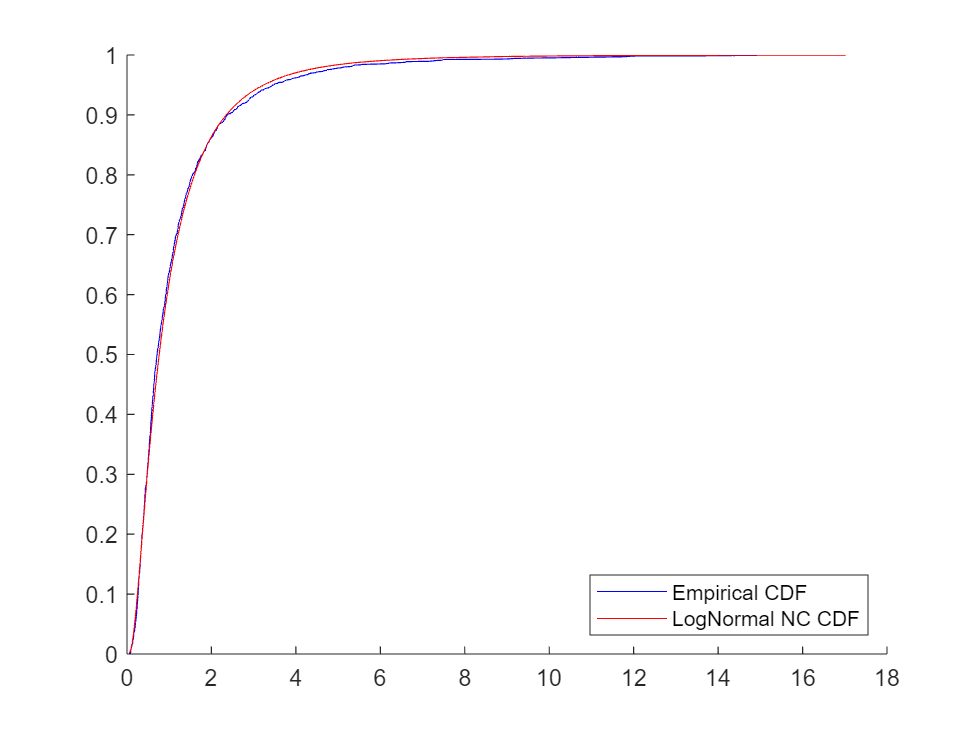

% Lognormal NO censoring
figure
hold on
plot(ecdf_NC_val, ecdf_NC_cfr, 'b');
plot(ecdf_NC_val, expectLognormCdf_NC,'r');
legend('Empirical CDF','LogNormal NC CDF','Location','SE');

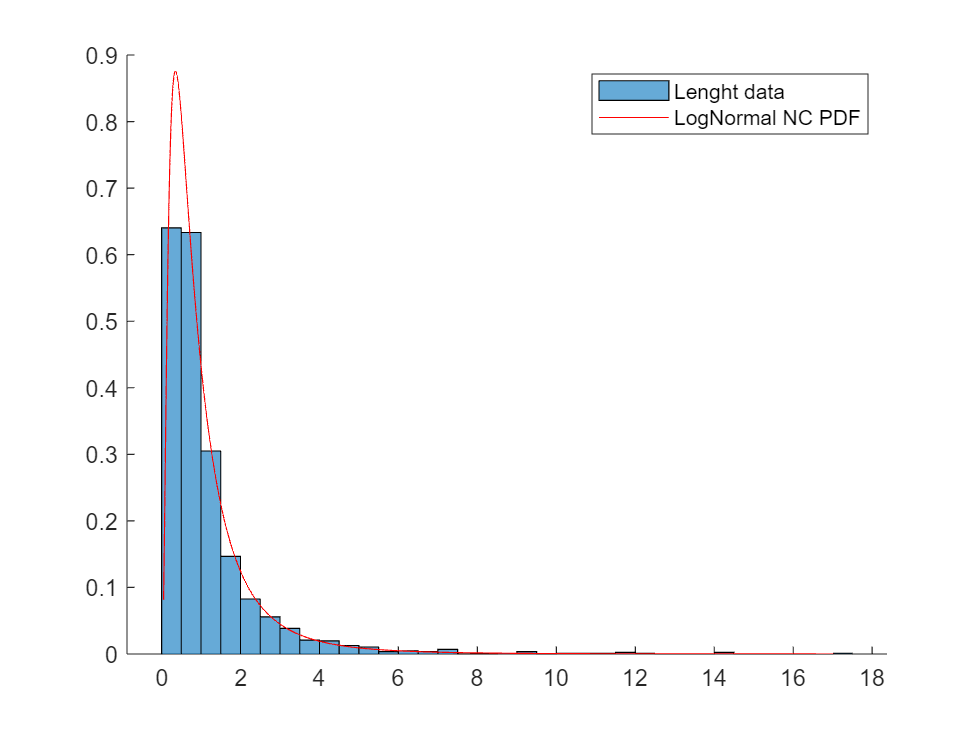

figure
hold on
histogram(length_data(:,2),'Normalization','pdf');
plot(ecdf_NC_val, expectLognormPdf_NC,'r');
legend('Lenght data','LogNormal NC PDF','Location','NE');

disp(char(Lognorm_NC_txt1,Lognorm_NC_txt2,Lognorm_NC_txt3,Lognorm_NC_txt4,Lognorm_NC_txt5))

K-S test for LogNormal length distribution with μ = -0.27097 - σ = 0.87857                                                                          
K statistics = 0.031008                                                                                                                             
p-value = 0.62557                                                                                                                                   
Ho = 0                                                                                                                                              
No evidence against Ho of no difference with LogNormal_NC distr. -> Ho retained -> a LogNormal_NC length distribution is detected at 5% significance


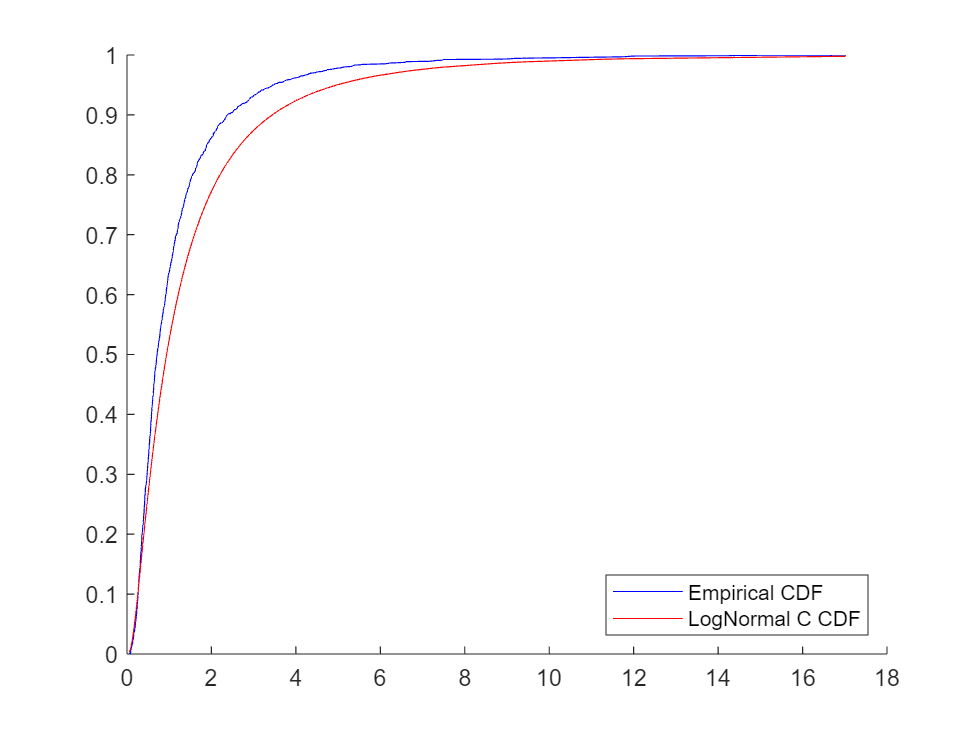

% Lognormal with censoring
figure
hold on
plot(ecdf_NC_val, ecdf_NC_cfr, 'b');
plot(ecdf_C_val, expectLognormCdf_C,'r');
legend('Empirical CDF','LogNormal C CDF','Location','SE');

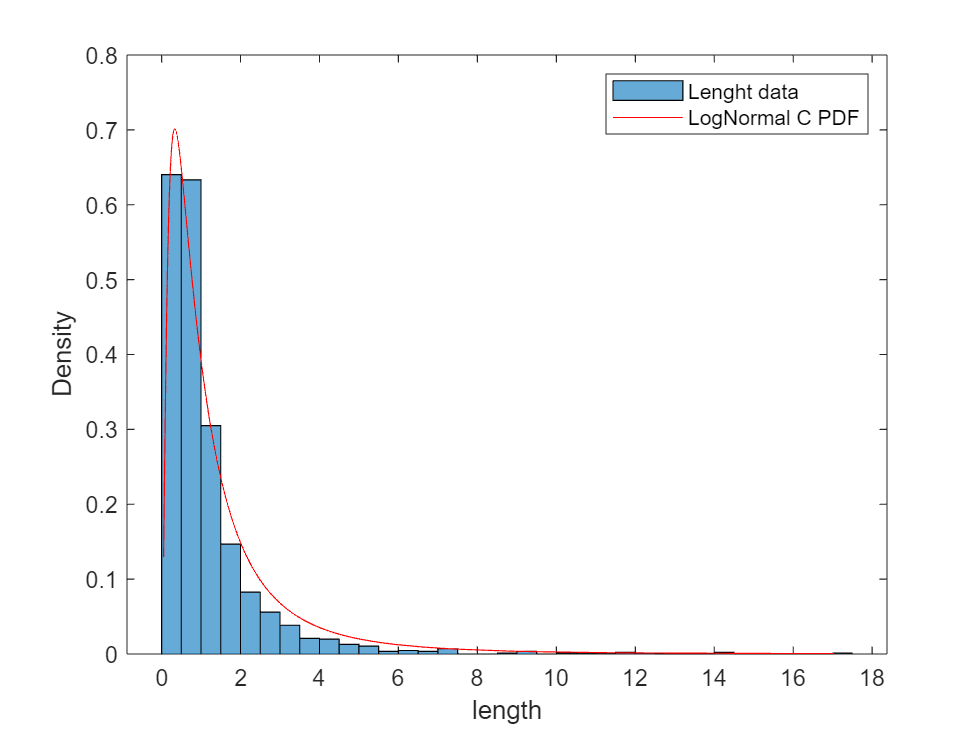

figure
hold on
histogram(length_data(:,2),'Normalization','pdf');
plot(ecdf_C_val, expectLognormPdf_C,'r');
box on
xlabel('length'); ylabel('Density')
legend('Lenght data','LogNormal C PDF','Location','NE');

disp(char(Lognorm_C_txt1,Lognorm_C_txt2,Lognorm_C_txt3,Lognorm_C_txt4,Lognorm_C_txt5))

K-S test for LogNormal length distribution with μ = -0.063857 - σ = 1.0141                                                                        
K statistics = 0.046892                                                                                                                           
p-value = 0.25949                                                                                                                                 
Ho = 0                                                                                                                                            
No evidence against Ho of no difference with LogNormal_C distr. -> Ho retained -> a LogNormal_C length distribution is detected at 5% significance


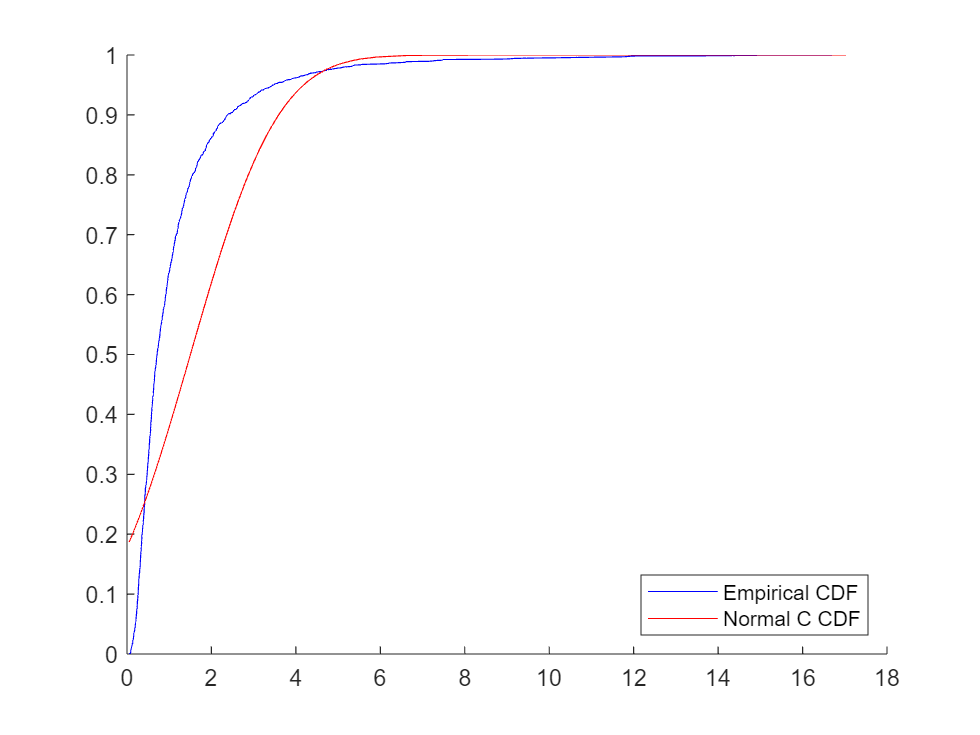

% Normal with censoring
figure
hold on
plot(ecdf_NC_val, ecdf_NC_cfr, 'b');
plot(ecdf_C_val, expectNormCdf_C,'r');
legend('Empirical CDF','Normal C CDF','Location','SE');

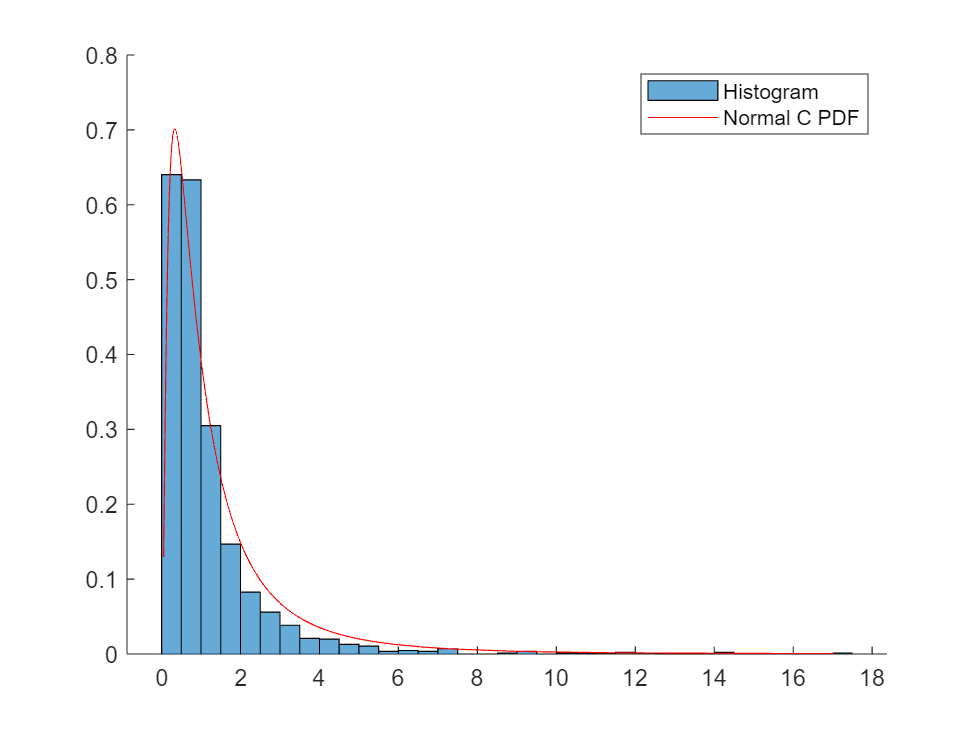

figure
hold on
histogram(length_data(:,2),'Normalization','pdf');
plot(ecdf_C_val, expectLognormPdf_C,'r');
legend('Histogram','Normal C PDF','Location','NE');

disp(char(Norm_C_txt1,Norm_C_txt2,Norm_C_txt3,Norm_C_txt4,Norm_C_txt5))

K-S test for Normal length distribution with Mean = 1.5022 - St. dev = 1.6308                                                                    
K statistics = 0.241                                                                                                                             
p-value = 7.9178e-24                                                                                                                             
Ho = 1                                                                                                                                           
Strong evidence against Ho of no difference with Normal_C distr. -> Ho rejected -> no Normal_C length distribution is detected at 5% significance


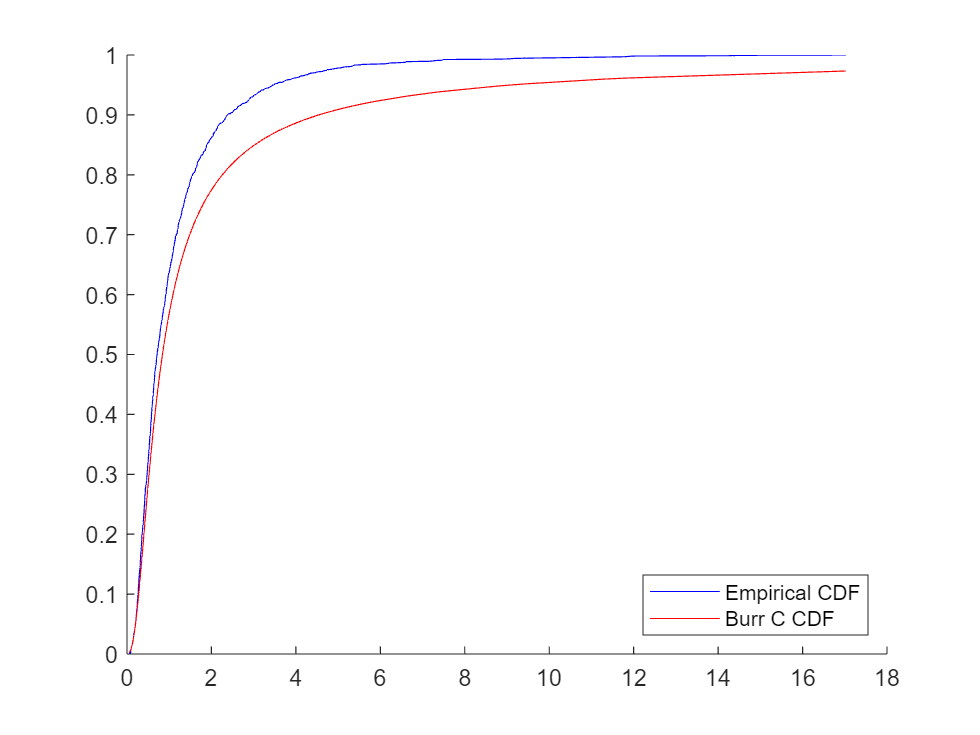

% Burr with censoring
figure
hold on
plot(ecdf_NC_val, ecdf_NC_cfr, 'b');
plot(ecdf_C_val, expectBurrCdf_C,'r');
legend('Empirical CDF','Burr C CDF','Location','SE');

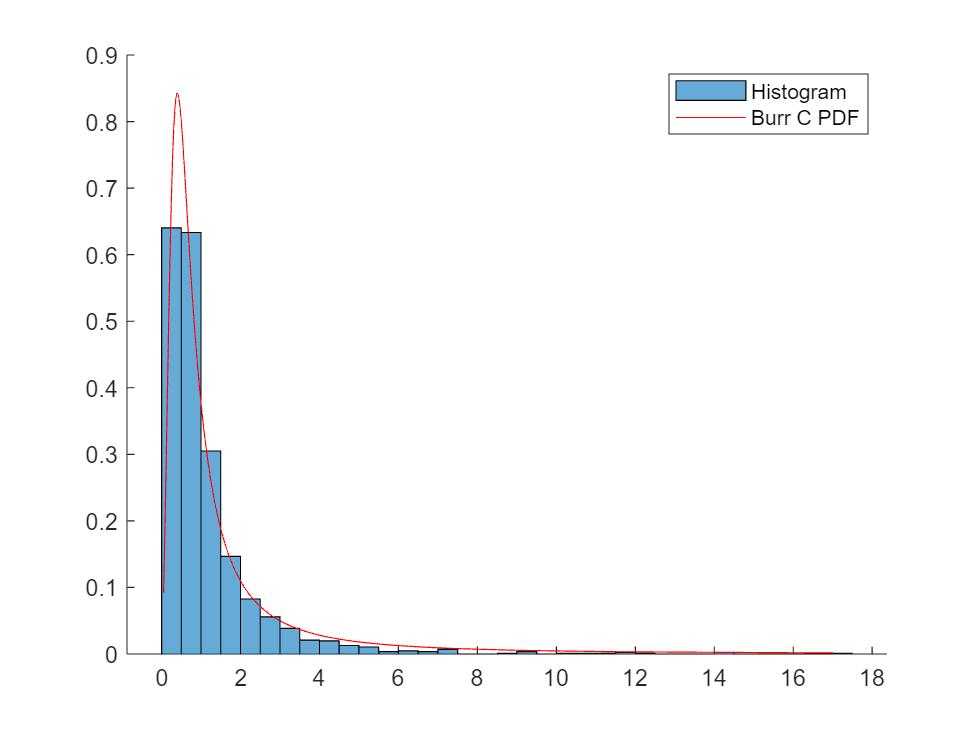

figure
hold on
histogram(length_data(:,2),'Normalization','pdf');
plot(ecdf_C_val, expectBurrPdf_V,'r');
legend('Histogram','Burr C PDF','Location','NE');

disp(char(Burr_C_txt1,Burr_C_txt2,Burr_C_txt3,Burr_C_txt4,Burr_C_txt5))

K-S test for Burr length distribution with c = 2.4579 - k = 0.40695-  alpha =0.45549                                                    
K statistics = 0.029444                                                                                                                 
p-value = 0.8161                                                                                                                        
Ho = 0                                                                                                                                  
No evidence against Ho of no difference with Burr_C distr. -> Ho retained -> a Burr_C length distribution is detected at 5% significance


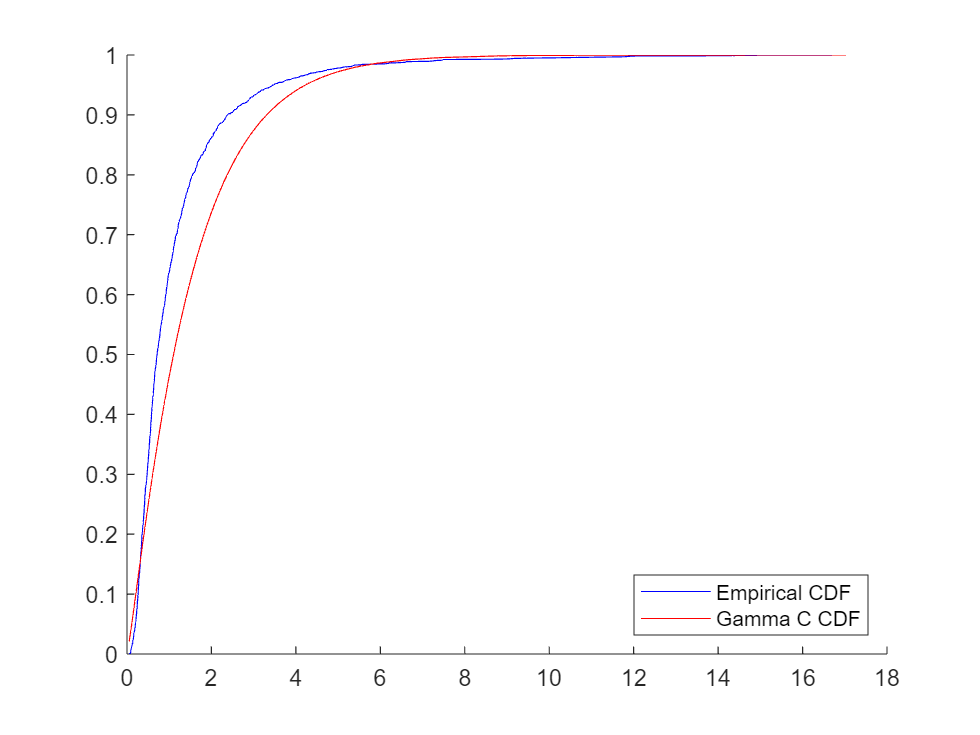

% Gamma with censoring
figure
hold on
plot(ecdf_NC_val, ecdf_NC_cfr, 'b');
plot(ecdf_C_val, expectGammaCdf_C,'r');
legend('Empirical CDF','Gamma C CDF','Location','SE');

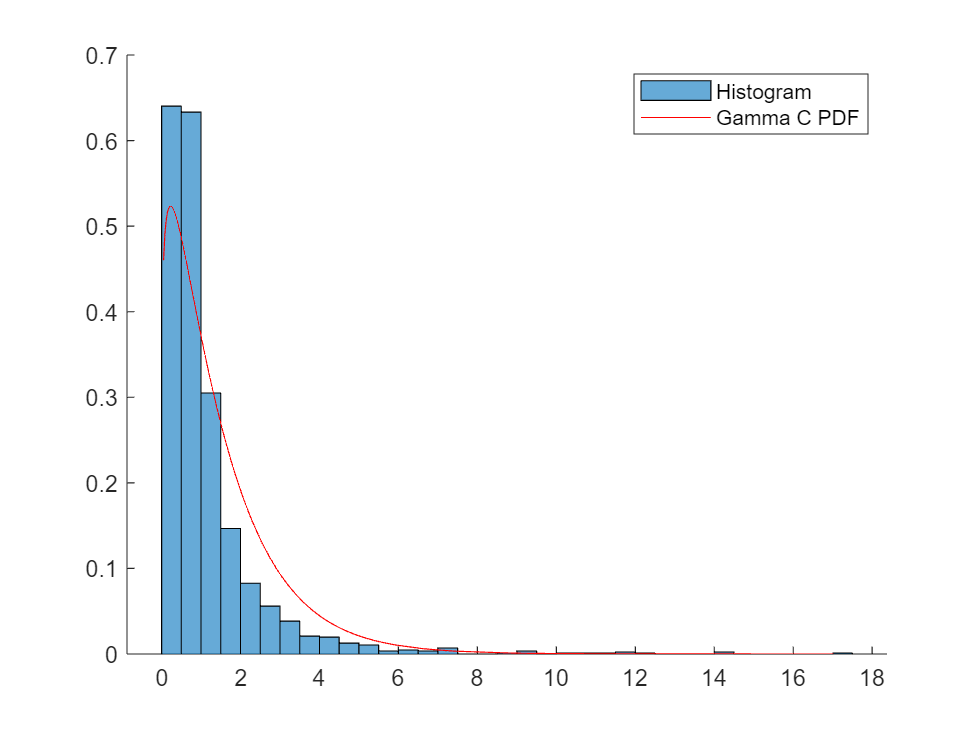

figure
hold on
histogram(length_data(:,2),'Normalization','pdf');
plot(ecdf_C_val, expectGammaPdf_V,'r');
legend('Histogram','Gamma C PDF','Location','NE');

disp(char(Gamma_C_txt1,Gamma_C_txt2,Gamma_C_txt3,Gamma_C_txt4,Gamma_C_txt5))

K-S test for Gamma_C length distribution with a = 1.181 - b = 1.2672                                                                           
K statistics = 0.10905                                                                                                                         
p-value = 3.232e-05                                                                                                                            
Ho = 1                                                                                                                                         
Strong evidence against Ho of no difference with Gamma_C distr. -> Ho rejected -> no Gamma_C length distribution is detected at 5% significance


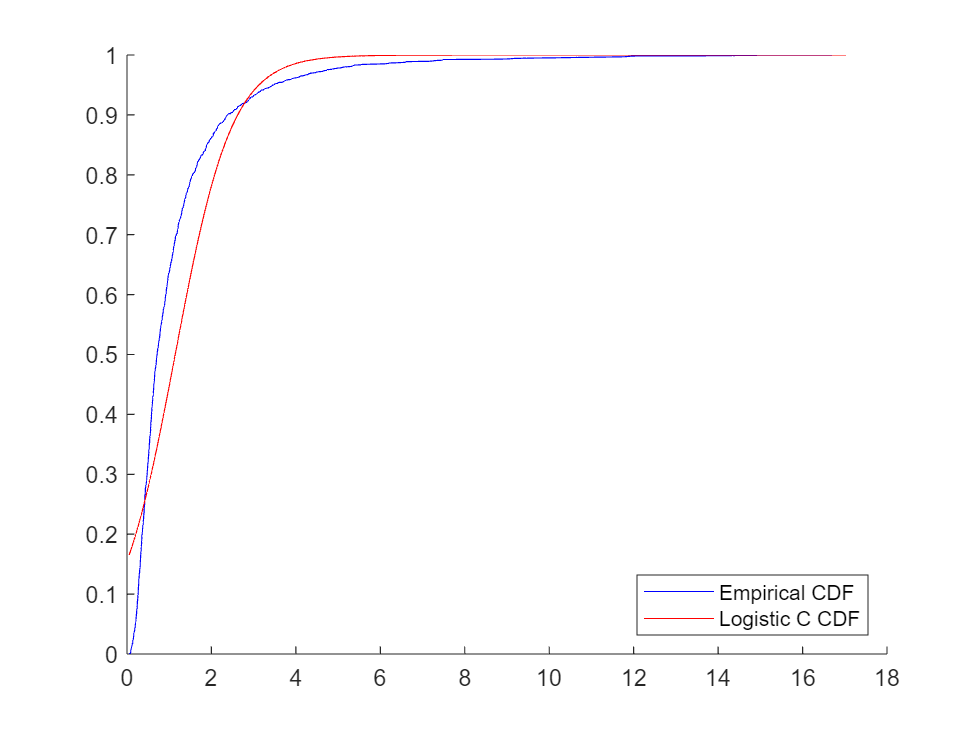

% Logistic with censoring
figure
hold on
plot(ecdf_NC_val, ecdf_NC_cfr, 'b');
plot(ecdf_C_val, expectLogisticCdf_C,'r');
legend('Empirical CDF','Logistic C CDF','Location','SE');

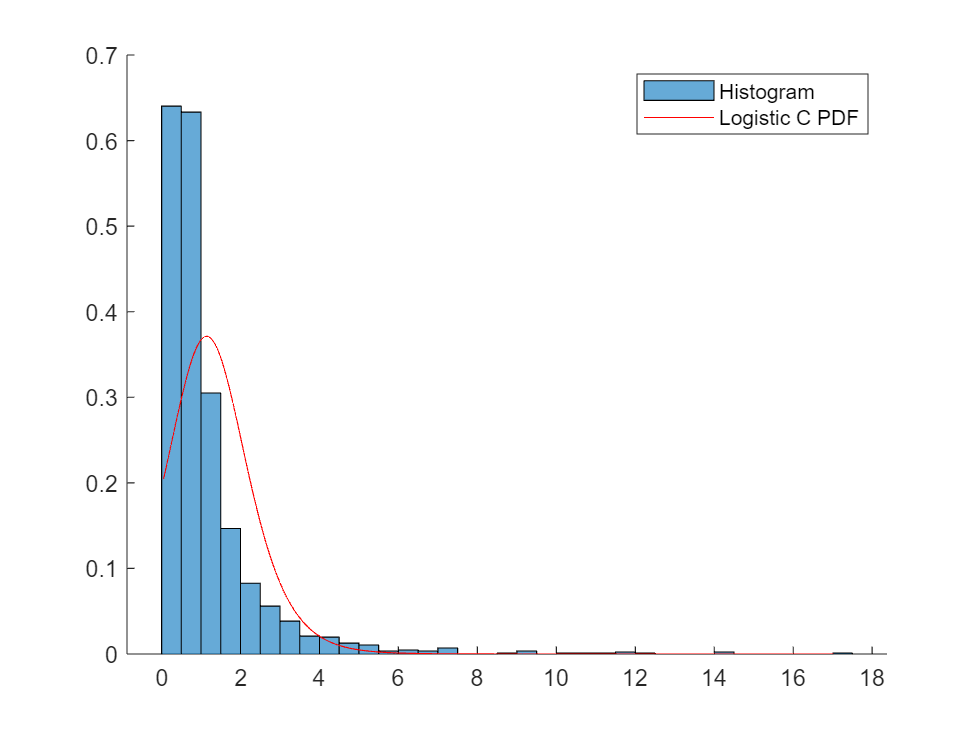

figure
hold on
histogram(length_data(:,2),'Normalization','pdf');
plot(ecdf_C_val, expectLogisticPdf_V,'r');
legend('Histogram','Logistic C PDF','Location','NE');


disp(char(Logistic_C_txt1,Logistic_C_txt2,Logistic_C_txt3,Logistic_txt4,Logistic_C_txt5))

K-S test for Logistic length distribution with μ = 1.1422 - σ = 0.67353                                                                              
K statistics = 0.18321                                                                                                                               
p-value = 5.9889e-14                                                                                                                                 
Ho = 1                                                                                                                                               
Strong evidence against Ho of no difference with Logistic_C distr. -> Ho rejected -> no Logistic_C length distribution is detected at 5% significance
